## **EXERCISE 3**

% Exercise 3
clc, clearvars, close all

**Task**: forecast the real price of gasoline for the US.

**Dataset**: gasoline.xlsx contains two monthly time series. The nominal price of gasoline and the CPI. 

- Create the real price of gasoline

- Plot real and nominal prices over time

- From now on you will work with logs: yt = log (Real Pricet). Consider the sample from obs 1 to Dec 2014. Plot the sample ACF of yt and that of Dyt = (yt - yt-1).

- Using the same sample above fit two AR(1) models: the first for yt and the second for Dyt. Report in both cases the coefficient associated with the lagged dependent variable.

- Produce a series of 1 step-ahead forecasts for yt. Use the following models: random walk (no drift), ARIMA(1,1,0), ARIMA(0,1,1), ARIMA(1,1,1). To produce forecasts start from the sample that ends in Dec 2014 and add 1 observation at the time (i.e. expanding/recursive scheme)

- Transform the forecasts to levels (i.e. real prices)

- Compute the mean squared forecast error and comment.

data = readtable("gasoline_clean.xlsx");

% Rename variables
data = renamevars(data, ["observation_date", "GASREGW", "CPIAUCSL"], ...
    ["date", "nominal_price", "CPI"]);

% Make it a timetable
data = table2timetable(data);

data(1:6,1:2)

ans = 6×2 timetable
       date        nominal_price     CPI 
    ___________    _____________    _____

    01-Nov-1990        1.324        133.7
    01-Dec-1990        1.341        134.2
    01-Jan-1991         1.18        134.7
    01-Feb-1991       1.0942        134.8
    01-Mar-1991         1.04        134.8
    01-Apr-1991       1.0762        135.1


**1)  Create the real price of gasoline.**

**2) Plot real and nominal prices over time**

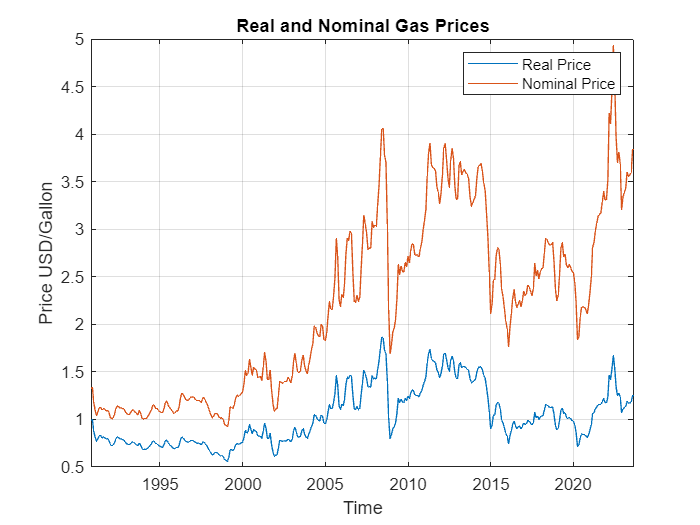

% Real price
data.real_price = (data.nominal_price ./ data.CPI) * 100;

% Plotting the data
figure;
plot(data.date, data.real_price, data.date, data.nominal_price);
legend('Real Price', 'Nominal Price');
xlabel('Time');
ylabel('Price USD/Gallon');
title('Real and Nominal Gas Prices');
grid on;

**3) From now on you will work with logs: yt = log (Real Pricet). Consider the sample from obs 1 to Dec 2014. Plot the sample ACF of yt and that of Dyt = (yt - yt-1).**

%% section 3
% log(real_price)
data.log_real_price = log(data.real_price);

% sample data 
sample_data = data(timerange("01-Nov-1990","02-Dec-2014"), :)

sample_data = 290×5 timetable
       date        nominal_price     CPI     real_price    log_real_price    delta_log_rp
    ___________    _____________    _____    __________    ______________    ____________

    01-Nov-1990        1.324        133.7     0.99028        -0.0097708                0 
    01-Dec-1990        1.341        134.2     0.99925       -0.00074543        0.0090254 
    01-Jan-1991         1.18        134.7     0.87602          -0.13237         -0.13162 
    01-Feb-1991       1.0942        134.8     0.81176          -0.20855        -0.076187 
    01-Mar-1991         1.04        134.8     0.77151           -0.2594        -0.050848 
    01-Apr-1991       1.0762     

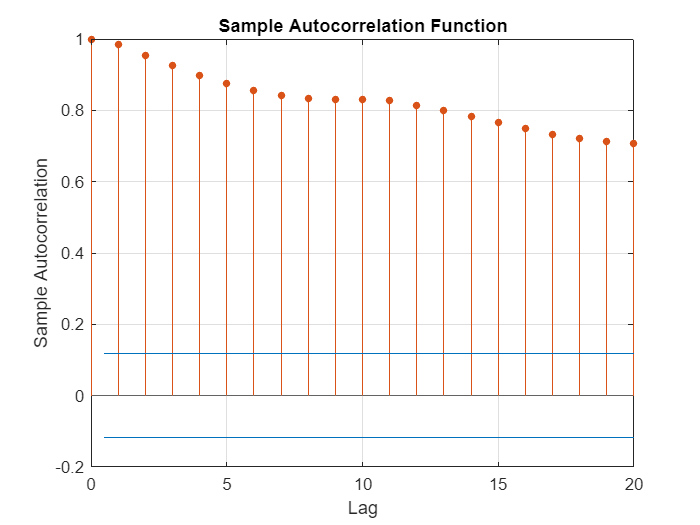

% from econometrics toolbox
% ACF log real price
[acf, lags] = autocorr(sample_data.log_real_price); 
autocorr(sample_data.log_real_price)

Since the positive and large autocorrelations that slowly decreases, we see the presence of a trend.

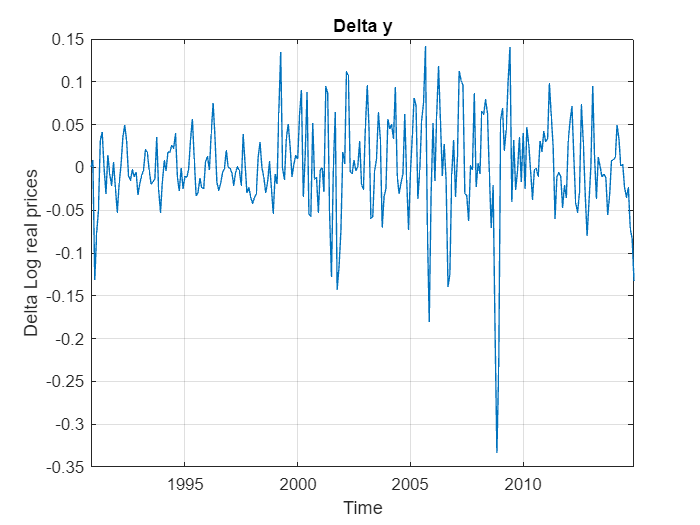

% compute delta_y = (y_t - y_t-1)
time = sample_data.date(2:end);
time = [datetime("01-Nov-1990", 'InputFormat', 'dd-MMM-yyyy'); time]; % add the first date at the beginning to match the series length 
delta_log_rp = diff(sample_data.log_real_price); % compute the difference
delta_log_rp = [0; delta_log_rp]; % add zero value at the beginning to match the series length

sample_data.delta_log_rp = delta_log_rp;
data.delta_log_rp = [0; diff(data.log_real_price)];

plot(sample_data.date, sample_data.delta_log_rp); title('Delta y'); grid on;
xlabel('Time'); ylabel('Delta Log real prices')

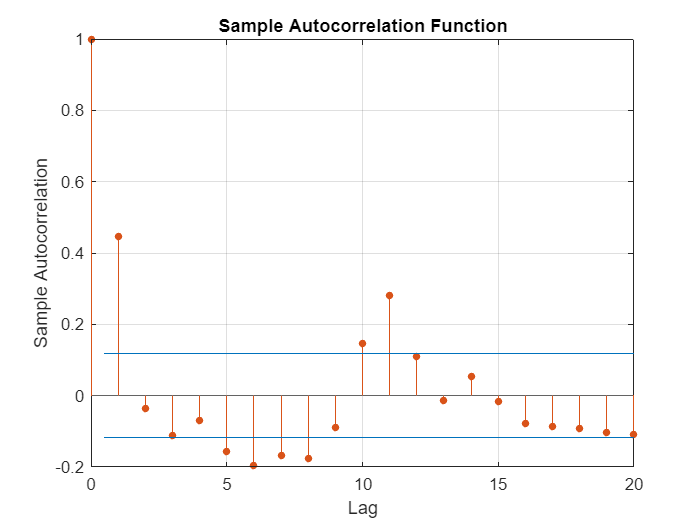

% ACF log real price
autocorr(sample_data.delta_log_rp(2:end))

We can see the presence of seasonality inside the series of the Gas prices variation.

**4) Using the same sample above fit two AR(1) models: the first for yt and the second for Dyt. Report in both cases the coefficient associated with the lagged dependent variable**

"Many observed time series exhibit serial autocorrelation; that is, linear association between lagged observations. This suggests past observations might predict current observations. The autoregressive (AR) process models the conditional mean of *yt* as a function of past observations, *yt*−1,*yt*−2,…,*yt*−*p*. An AR process that depends on *p* past observations is called an AR model of degree *p*, denoted by AR(*p*)." 

(source: https://it.mathworks.com/help/econ/specify-ar-models.html)

%% section 4
clc, close all


% Fitting AR(1) model for log real price

mdl_lrp = arima(1, 0, 0); % ARIMA(1,0,0) represents an AR(1) model
est_lrp = estimate(mdl_lrp, sample_data.log_real_price(1:end-1)); % Estimate the model parameters

 
    ARIMA(1,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0003354      0.0035073       0.095627        0.92382
    AR{1}         0.98557        0.01177         83.737              0
    Variance    0.0029837     0.00014458         20.637     1.2903e-94



coef_lrp = est_lrp.AR{1}; % Get the coefficient associated with the lagged dependent variable

[fore,var] = forecast(est_lrp, 105, sample_data.log_real_price(1:end)); % forcasts and var from 01-Dec-2014 to 2023

mean(fore)

ans = 0.0488

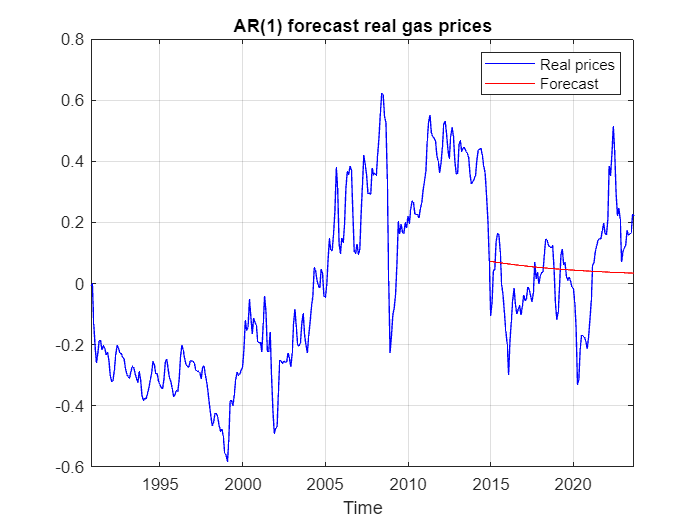


 plot(data.date, data.log_real_price', '-b', ...    % plot real values
    data.date, [NaN(1,290), fore'], '-r');          % plot forecast
legend ('Real prices', 'Forecast'); xlabel('Time')
title('AR(1) forecast real gas prices'); grid on

% Fitting AR(1) for delta lrp

mdl_dlrp = arima(1, 0, 0); % ARIMA(1,0,0) represents an AR(1) model
est_dlrp = estimate(mdl_dlrp, sample_data.delta_log_rp(1:end-1)); % Estimate the model parameters

 
    ARIMA(1,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    0.00028516      0.0030514       0.093451        0.92555
    AR{1}           0.4454       0.030699         14.508     1.0711e-47
    Variance     0.0024129     0.00013383          18.03     1.1264e-72



coef_dlrp = est_dlrp.AR{1}; % Get the coefficient associated with the lagged dependent variable

[dfore,dvar] = forecast(est_dlrp, 105, data.delta_log_rp(1:end)); % forcasts and var from 01-Dec-2014 to 2023

mean(dfore)

ans = 4.7256e-04

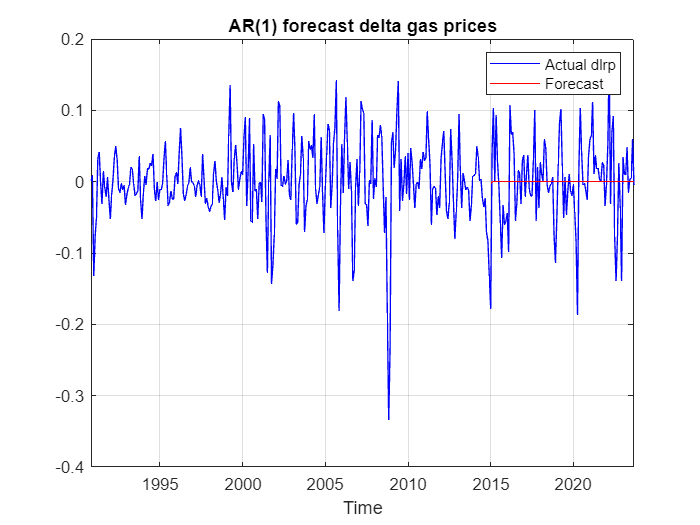


 plot(data.date, data.delta_log_rp', '-b', ...    % plot real values dlrp
    data.date, [NaN(1,290), dfore'], '-r');          % plot forecast
legend ('Actual dlrp', 'Forecast'); xlabel('Time')
title('AR(1) forecast delta gas prices'); grid on

**5)  Produce a series of 1 step-ahead forecasts for yt. Use the following models: random walk (no drift), ARIMA(1,1,0), ARIMA(0,1,1), ARIMA(1,1,1). To produce forecasts start from the sample that ends in Dec 2014 and add 1 observation at the time (i.e. expanding/recursive scheme)**

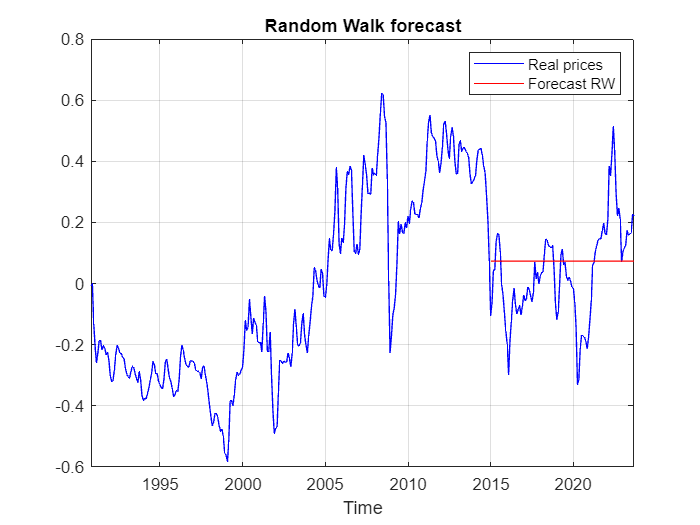

% Random Walk (no drift)
% forcasted values are all equal to y_t(t = "01-Dec-2014")
forecasted_values_RW = [NaN(1, 290), ones(1, 105) * data.log_real_price(290)]; % array of NaN until Dec-2014 (290)


plot(data.date, data.log_real_price', '-b', ...     % plot real prices
    data.date, forecasted_values_RW, '-r');         % plot forcast
title('Random Walk forecast'); legend('Real prices', 'Forecast RW'); xlabel('Time'); grid on

% ARIMA(1,1,0)
% ARIMA(0,1,1)
% ARIMA(1,1,1)

